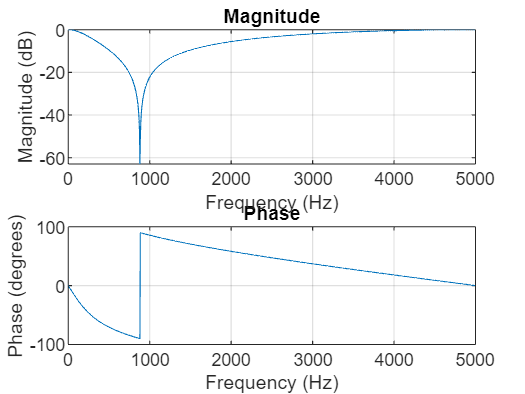

% LPF Chebyshev Type I IIR
clc;
clear all;
close all;

wp=input('Enter pass band frequency: ');
ws=input('Enter stop band frequency: ');
deltap=input('Enter pass band ripple: ');
deltas=input('Enter stop band ripple: ');

% Design a low-pass Chebyshev Type I filter
cutoff_frequency = 1000; % Adjust as needed

omegap = (2/fs)*tan(wp/2);
omegas = (2/fs)*tan(ws/2); 
den = 2*log10(omegas/omegap);
delta = ((1/(deltas^2))-1);
epsi  = ((1/(deltap^2))-1);
num = log10(delta/epsi);
order = ceil(num/den);
rp = -20*log10(1/deltap); % Passband ripple in dB

[b, a] = cheby1(order, rp, [0.1,0.3], 'stop');

% Plot the frequency response of the filter
freqz(b, a, 1000, fs);